`考虑非对称的单峰光谱``，光谱设计需要考虑中心波长、半高全宽（``FWHM``）等参数，例如设定一个``FWHM``参数，修改中心波长的值。分析白光干涉信号在空域和谱域的特征，对得到的白光干涉信号测量，和理想值比较。`

% %生成非对称光谱
% clc;clear all;
% wl = linspace(0.1,1.2,1024);
% gv1 = 100;
% sigma1 = 0.065;
% u1 = 0.7;
% guass1 = guassf(wl,gv1,sigma1,u1);
% plot(wl,guass1)
% gv2 = gv1/1;
% guass2 = guassf(wl,gv2,0.26,0.6); 
% guass3 = guass1 + guass2;
% plot(wl,guass3)
% %固定光谱中心波数，改变非对称光谱的FWHM
% ccwl = ccwlf(wl,guass3)
% fwhm = fwhmf(wl,guass3)
% spectrum_frequency = wl;
% spectrum_intensity = guass3;
% z0 = 20;    %单位为微米
% N = 40000;
% z = -10:50/40000:(N-1)*(50/40000);
% interference_signal = zeros(1,length(z));
% for i = 1:length(z)
%         interference_signal(i) = sum(spectrum_intensity./2+...
%         spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(1./spectrum_frequency)));
% end
% disp("生成的白光干涉信号");
% plot(z,interference_signal);
% interference_signal = interference_signal-mean(interference_signal);
% baoluo = hilbert(interference_signal); % Hilbert变换
% baoluo = abs(baoluo);
% plot(z,interference_signal,z,baoluo,'--','linewidth',1.5);

改变光谱的中心波长和半高宽（FWHM）.

当中心波长为655时，半高宽分别为0~300，通过设置$\sigma$来改变半高宽。

% %生成白光干涉信号
% gv1 = 100;
% V = zeros(1,20);
% W = zeros(1,20);
% fwhm1 = zeros(1,20);
% for n = 1:20
% sigma1 = 0.005*n;
% u1 = 0.7;
% guass1 = guassf(wl,gv1,sigma1,u1);
% % plot(wl,guass1)
% gv2 = gv1/1;
% guass2 = guassf(wl,gv2,0.26,0.6); 
% guass3 = guass1 + guass2;
% spectrum_frequency = wl;
% spectrum_intensity = guass3;
% z0 = 20;    %单位为微米
% N = 40000;
% z = -10:50/40000:(N-1)*(50/40000);
% interference_signal = zeros(1,length(z));
% for i = 1:length(z)
%         interference_signal(i) = sum(spectrum_intensity./2+...
%         spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(1./spectrum_frequency)));
% end
% %disp("生成的白光干涉信号");
% % plot(z,interference_signal);
% %计算零级条纹与第一级条纹的可见度和干涉条纹的空间长度
% V(n) = calcuV(interference_signal);
% W(n) = calcuW(z,interference_signal);
% fwhm1(n) = fwhmf(spectrum_frequency,guass3);
% end
% plot(fwhm1,V);
% plot(fwhm1,W);

从空域来看，如果白光干涉信号光谱不是高斯形状，而是单峰非对称光谱。在不存在色散和相位噪声等影响因素下，由单峰非对称光谱生成的白光干涉信号包络不再是高斯高斯形状。与高斯光谱形成的白光干涉信号对比，不同光谱形成的白光干涉信号包络不同。这对于通过相干峰寻址法来获得物体表面形貌高度存在一定的影响。在白光干涉信号中，若零级条纹和邻近强度最大的条纹之间一般强度相差较小，则很难将两者区分开来，使得干涉仪的绝对测量产生较大的误差。通过计算单峰非对称光谱生成的白光干涉信号零级条纹与第一级条纹的可见度和干涉条纹空间长度，可以得到相同中心波长，随着光谱的半高宽增加，其零级条纹与第一级条纹的可见度增加，干涉条纹空间长度逐渐减小。这表明单峰非对称光谱可以通过增加光谱FWHM来改变白光干涉信号的可见度和干涉条纹空间长度，从而提高白光干涉测量精度。相比于高斯光谱，单峰非对称光谱得到的白光干涉信号的可见度变化较小且光谱FWHM在0~200nm范围内可见度和条纹宽度均好于高斯光谱。

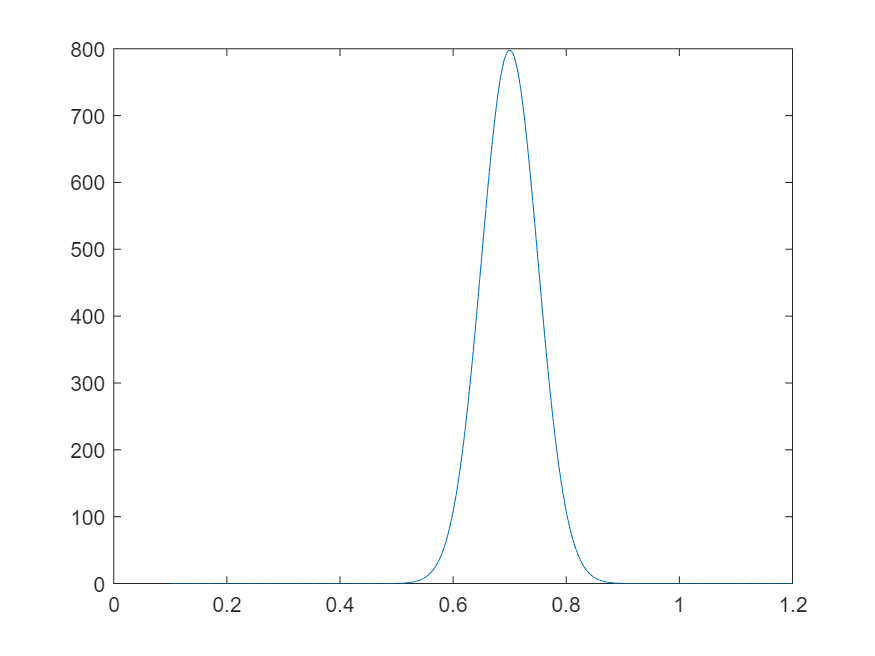

%对白光干涉信号作傅里叶变换，选择正频域部分，然后再作傅里叶逆变换，可以白光干涉信号的幅度谱和相位谱。
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
clear all; clc;
wl = linspace(0.1,1.2,1024);
gv1 = 100;
sigma1 = 0.05;
u1 = 0.7;
guass1 = guassf(wl,gv1,sigma1,u1);
plot(wl,guass1)

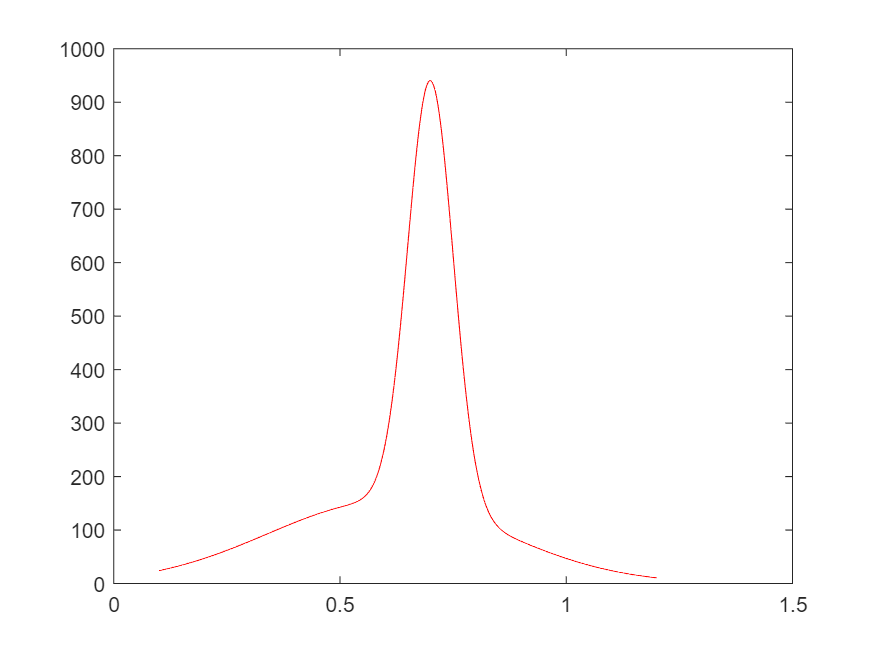

gv2 = gv1/1;
guass2 = guassf(wl,gv2,0.26,0.6); 
guass3 = guass1 + guass2;
spectrum_frequency = wl;
spectrum_intensity = guass3;
plot(spectrum_frequency,spectrum_intensity,'r');
xlim([0 1.5])

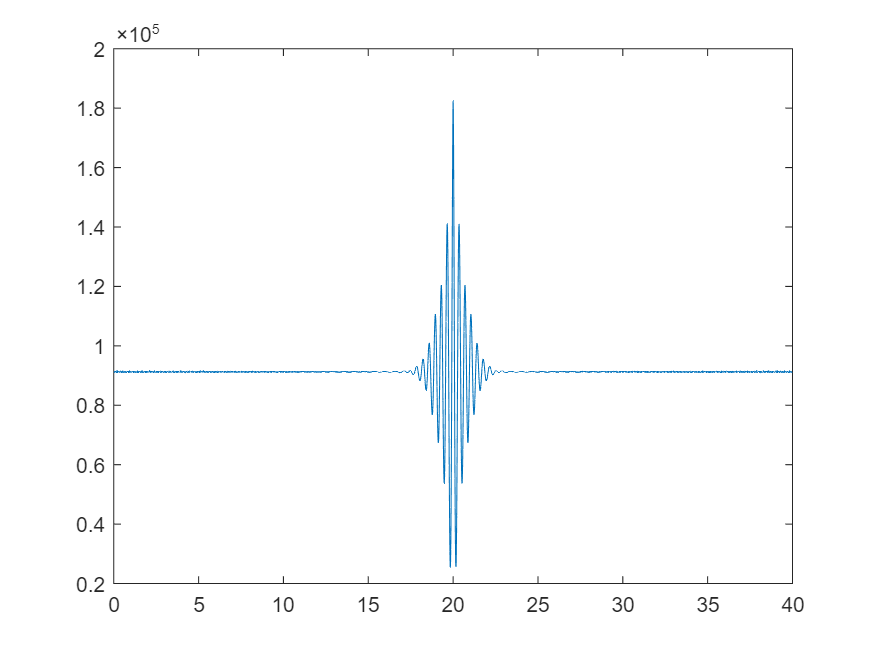

%生成白光干涉信号
z0 = 20;    %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*(1./spectrum_frequency)));
end
plot(z,interference_signal);

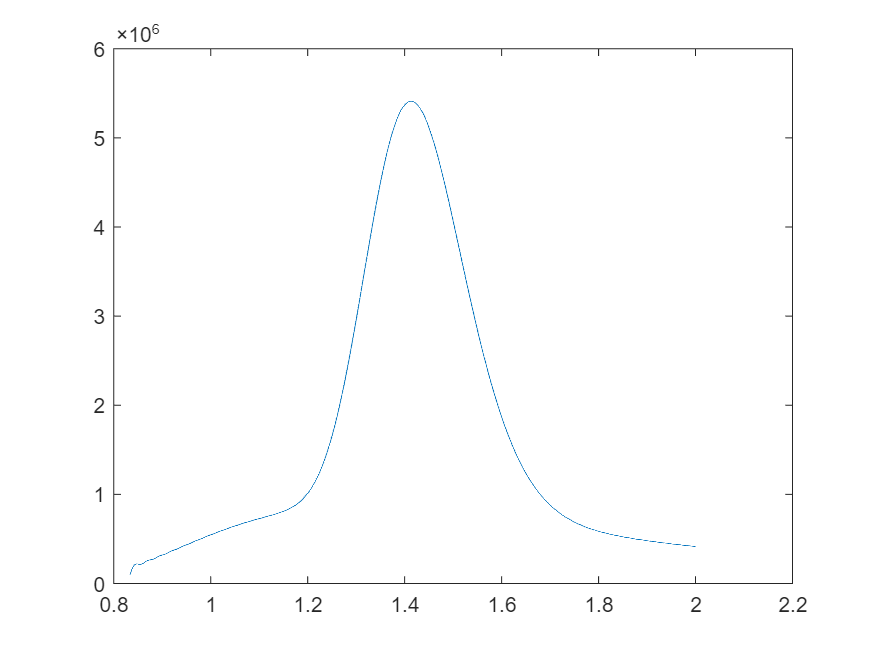

interference_signal = interference_signal-mean(interference_signal);
%fft补零
Nftt = 2^18;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1));
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1/1.2));
[~, indix_max] = min(abs(sigma-2));
% ang_fis = unwrap(ang_fis(indix_min:indix_max));
plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max));

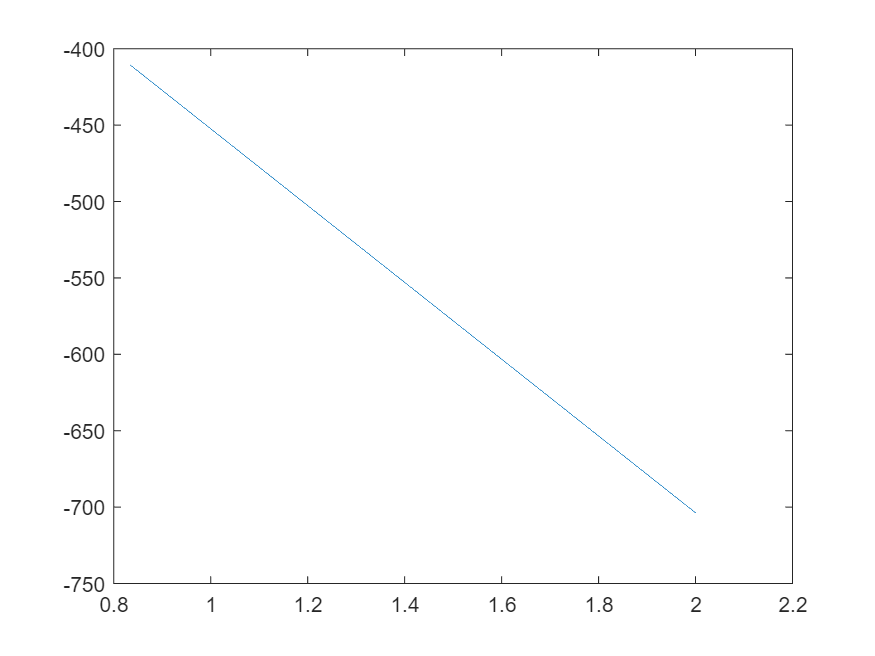

plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max));

p1 = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),1)

p1 = 	1.0e+00 *

 -251.3274 -201.0619


p1(1) = p1(1)-4*pi*z(1);
%计算z0,误差
a01 = wrapToPi(p1(2))

a01 =      3.128033956301124e-06


p1(1) = p1(1)-4*pi*z(1)

p1 = 	1.0e+00 *

 -251.3274 -201.0619


calculate_z0 = p1(1)/(-4*pi)

calculate_z0 =   20.000000197834840


diff_z0 = abs(calculate_z0-z0)

diff_z0 =      1.978348400655250e-07


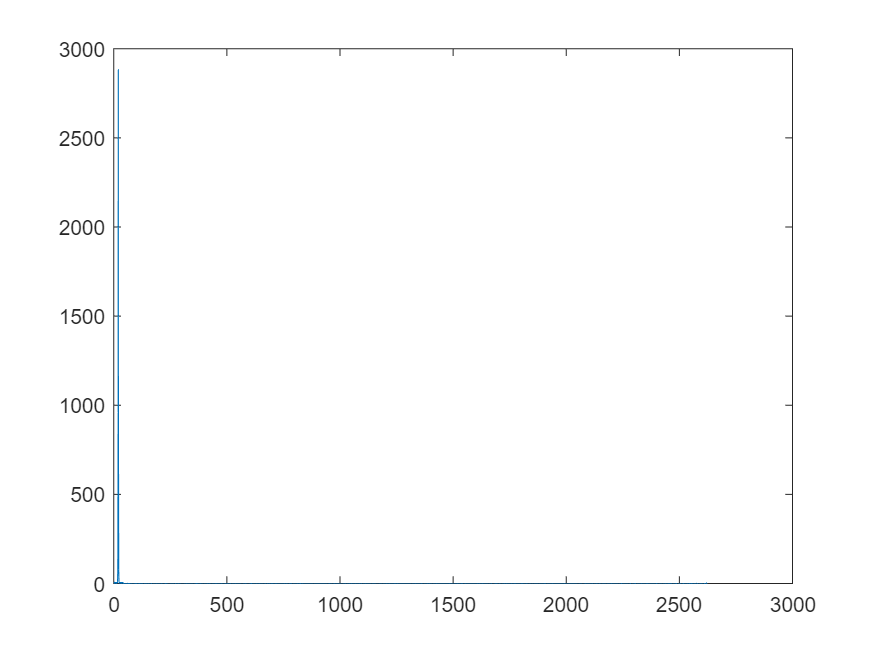

pSigma = -4*pi*calculate_z0*sigma;
F_sigma = abs_fis.*exp(1i*pSigma);

%逆傅里叶变换
Nifft = 2^22;
interference_signal1 = ifft(F_sigma,Nifft);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
zData = (1:Nifft)*deltaZ;
intensity = abs(interference_signal1);
phase = angle(interference_signal1);
plot(zData,intensity);

% plot(zData,phase);
[~,index3]= max(intensity);
% plot(zData,intensity);xlim([zData(index3)-2 zData(index3)+2]);
% plot(zData,phase);xlim([zData(index3)-2 zData(index3)+2]);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N

zp1 =   20.000625197842904


za1

za1 =   20.000624999999999


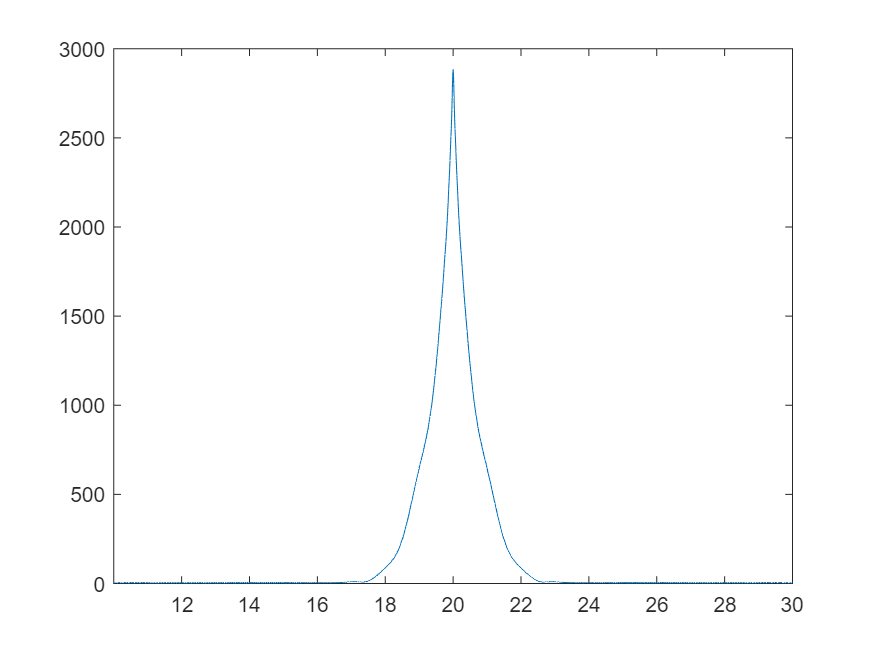


% end
plot(zData,intensity);xlim([zData(index3)-10 zData(index3)+10]);

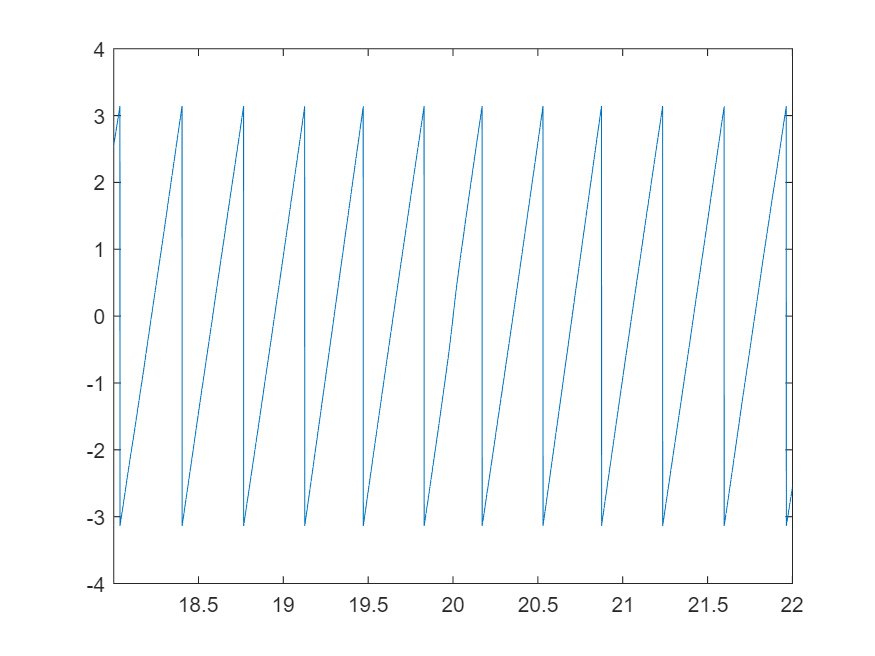

plot(zData,phase);xlim([zData(index3)-2 zData(index3)+2]);

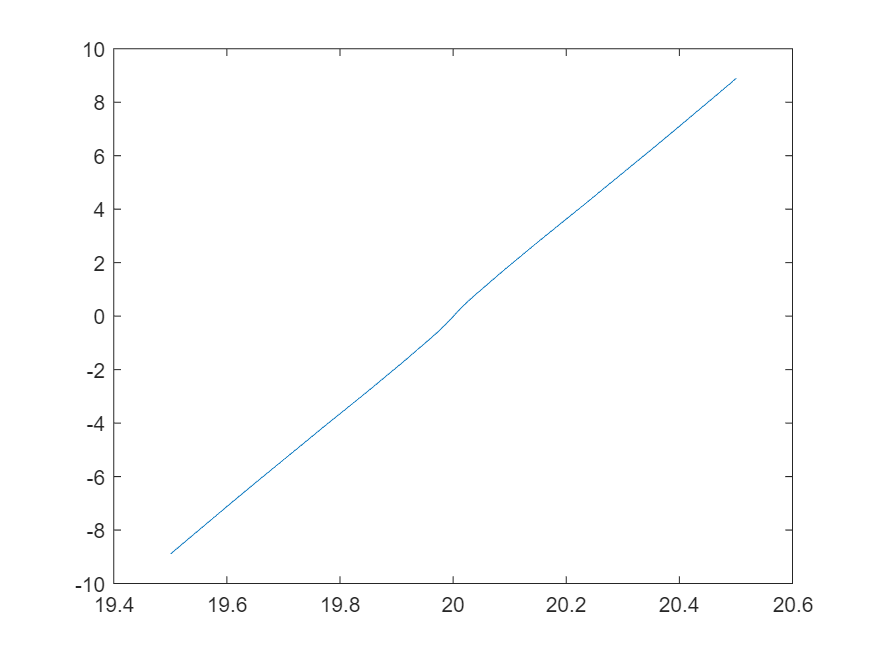

plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

通过非对称光谱生成白光干涉信号，对其作傅里叶变换，选择正频率部分得到白光干涉信号频域，其频域的幅度谱和相位谱分别为光谱和-4*pi*z0，其中z0为与物体表面形貌高度有关的量。对其作傅里叶逆变换，可以得到复数形式的白光干涉信号，其幅度谱与空域中的白光干涉信号包络有关。和空域的白光干涉信号包络类似，非对称光谱生成的白光干涉信号（复数形式）的幅度谱不再是高斯形状，但仍然关于幅度谱最大值对称。相位谱由于非对称光谱的影响，其相位不仅仅存在线性部分，还有非线性部分。这对于基于`基于相位解析的信号处理方法存在影响。固定中心波长，改变`FWHM。具体分析，幅度谱最大值和相位谱零点所在位置仍然相等。这里可以换不同guass3，应该的结果幅度谱的FWHM变化和白光干涉信号包络的变化趋势一样。`改变`FWHM会影响幅度谱，对于相位谱不影响。

同理，改变光谱的中心波长，相位谱会改变。包裹的相位谱周期会变小，斜率变大。plot(zData,phase);xlim([zData(index3)-2 zData(index3)+2]);这个画的就是包裹的相位谱。

function guass = guassf(wl,gv,sigma,u)
guass = gv/(sigma*sqrt(2*pi))*exp(-(wl-u).^2/(2*sigma^2));
end
function fwhm = fwhmf(wl,guass)
pks = max(guass);
idx = find(diff(sign(guass-pks/2)));
fwhmn = zeros(2,1);
for i = 1:numel(idx)
    x = wl(idx(i)-2:idx(i)+2);
    y = guass(idx(i)-2:idx(i)+2);
    fwhmn(i,:) = interp1(y,x,pks/2,'pchip');
end
fwhm = diff(fwhmn);
end

function ccwl1 = ccwlf(wl,guass)
P = sum(wl.*guass);
Q = sum(guass);
ccwl1 = P/Q;
end

条纹可见度公式：V= （I0-I1）/I0

%零级条纹与第一级条纹的可见度
function V = calcuV(signal)
[pks,~] = findpeaks(signal);
pks = sort(pks,'descend');
V = (pks(1)-pks(2))/pks(1);
end

%计算干涉条纹的空间长度
function wdt = calcuW(z,signal)
signal = signal-mean(signal);
%得到信号包络
W = hilbert(signal); % Hilbert变换
W = abs(W);
% plot(z,signal,z,W,'--','linewidth',1.5)
idx = find(diff(sign(W-max(W)/100)));
    for n = 1:numel(idx)
        idxrng = idx(n)-2:idx(n)+2;
        xfwhm(1,n) = interp1(W(idxrng), z(idxrng), max(W)/100, 'pchip');
    end
    wdt = xfwhm(end)-xfwhm(1);
end